% Goal: combine all DSP-image concepts—filtering, frequency, edges, and enhancement—into one small pipeline.
% Select your image, define a problem, and design a short script/report.

## Lab 6: Mini Project – Your Image Pipeline

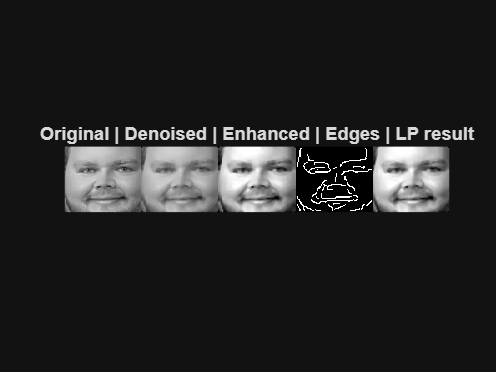

close all; clear; clc;

% 1) Load your own image (object, face, landscape, etc.)
I = im2double(im2gray(imread(fullfile(pwd, 'JD Vance.png'))));
% 2) Pre-process: noise removal
I_filt = medfilt2(I,[3 3]);

% 3) Enhance contrast
I_enh = imadjust(I_filt,[0.2 0.8],[0 1]);

% 4) Extract features (edges or frequency)
edges = edge(I_enh,'Canny',[0.1 0.25]);

% 5) Optional frequency-domain mask
F = fftshift(fft2(I_enh));
[M,N]=size(F);
[u,v]=meshgrid(-N/2:N/2-1,-M/2:M/2-1);
H = double(sqrt(u.^2+v.^2)<60);
I_lp = real(ifft2(ifftshift(F.*H)));

% 6) Visualization
figure; montage({I, I_filt, I_enh, edges, I_lp},'Size',[1 5]);
title('Original | Denoised | Enhanced | Edges | LP result');

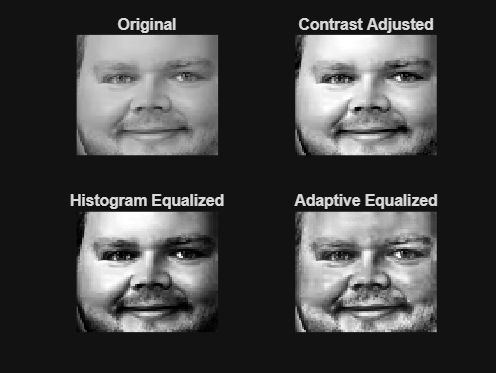


% 7) Extra
J1 = imadjust(I);
J2 = histeq(I);
J3 = adapthisteq(I);

figure;
subplot(2,2,1), imshow(I), title("Original");
subplot(2,2,2), imshow(J1), title("Contrast Adjusted");
subplot(2,2,3), imshow(J2), title("Histogram Equalized");
subplot(2,2,4), imshow(J3), title("Adaptive Equalized");

## 7) Report

- Describe your processing pipeline. 

Importing, grayscaling, removing noise and boosting contrast by predefined functions, edge extraction, frequency-domain filtering, and visualization.

- Explain how each stage relates to DSP operations. 

scaling, grayscaling,  fourier transform, displaying and subplotting.

- Discuss improvements or limitations.

Improvements: The contrast of bright part and dark part becomes more significant

Limitations: Information is lost, especially in the darkest part